# 3.1 A Scalar System

## System Values

A = -1;
b = 0;
c = 1;
d = 0;

eigValues = eig(A);
%Because eig = -1 the max. step size must be <=2 to achieve a stable system
%if using an FE

## Simulation Properties

x0 = 1;
h = 0.1       %steps size <= 0.1 achieves good results for FE

h = 0.1000

tend = 20;
t = 0:h:tend;
u = 0;

## Foward Euler

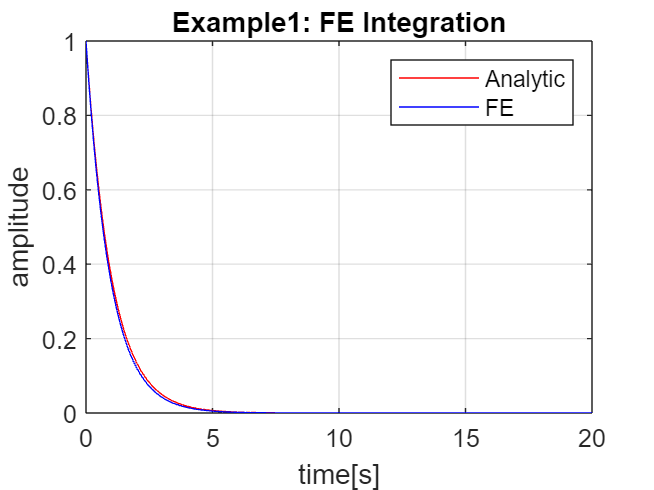

yFE = FE(A,b,c,d,u,h,tend,x0);
% Computing the analytical solution
yAN = x0*exp(A*t);

%Plotting FE vs Analytic Solution
figure(1);
plot(t,yAN,"red");
hold on;
plot(t,yFE,"blue");
hold off;
title('Example1: FE Integration');
ylabel('amplitude');
xlabel('time[s]');
legend('Analytic','FE');
grid on;

## Backward Euler

hBE = 0.3

hBE = 0.3000

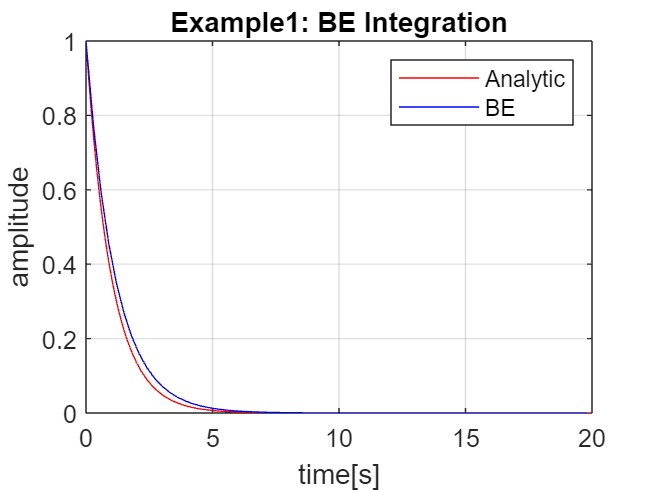

tBE = 0:hBE:tend;
yBE = BE(A,b,c,d,u,hBE,tend,x0); 

plot(t,yAN,"red");
hold on;
plot(tBE,yBE,"blue");
hold off;
title('Example1: BE Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('Analytic','BE');

## Runge-Kuta 4.Order

hRK4 = 2

hRK4 = 2

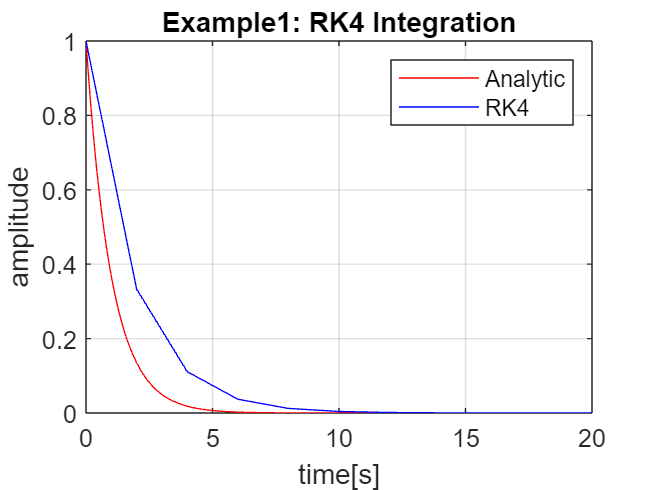

tRK4 = 0:hRK4:tend;
yRK4 = RK4(A,b,c,d,u,hRK4,tend,x0); 

plot(t,yAN,"red");
hold on;
plot(tRK4,yRK4,"blue");
hold off;
title('Example1: RK4 Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('Analytic','RK4');

## AB3 Solver

hAB3 = 0.5

hAB3 = 0.5000

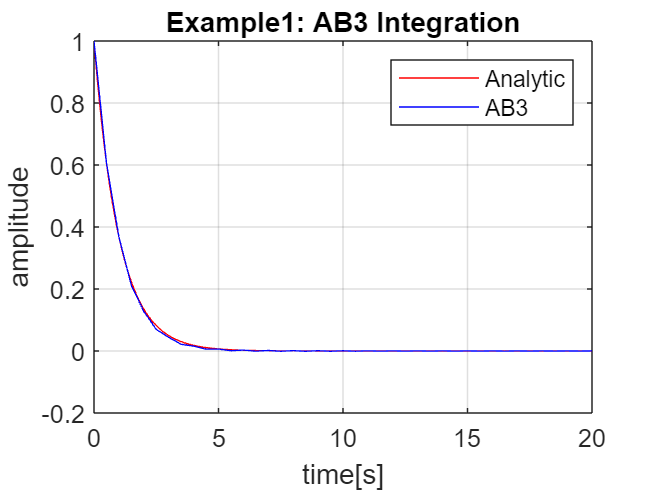

tAB3 = 0:hAB3:tend;
yAB3 = AB3(A,b,c,d,u,hAB3,tend,x0); 

plot(t,yAN,"red");
hold on;
plot(tAB3,yAB3,"blue");
hold off;
title('Example1: AB3 Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('Analytic','AB3');

## BDF3 Solver

hBDF3 = 1

hBDF3 = 1

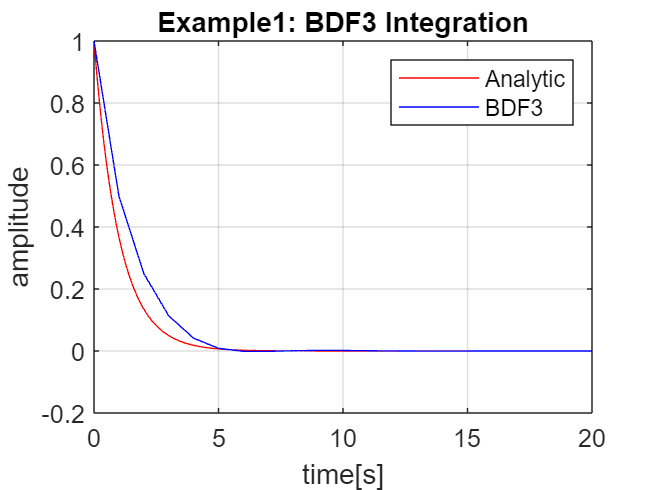

tBDF3 = 0:hBDF3:tend;
yBDF3 = BDF3(A,b,c,d,u,hBDF3,tend,x0);

plot(t,yAN,"red");
hold on;
plot(tBDF3,yBDF3,"blue");
hold off;
title('Example1: BDF3 Integration'); grid on;
ylabel('amplitude'); xlabel('time[s]'); legend('Analytic','BDF3');